# Monte-Carlo simulation

The goal here is to test the accuracy of the main result of the paper (Theorem 3) in the presence of measurement noise and amidst several types of transmission zeros.

% 1. Generate several 4 state, 2 input, 3 output, 2 fault systems
% 1.1 Make sure the zeros are also randomized. 1/4 have no zeros. 1/4 have
% one zero. 1/4 have two zeros. 1/4 have three zeros. Only finite zeros.

rng(1907);

scenario = struct();
Ns = 100;

nx = 5;
nu = 1;
ny = 3;
nf = 2;

for i = 1:Ns
    nz = floor(4*(i-1)/Ns);
    [A,B,C,D,F,G] = generate_random_lti_faulty_system(nx,nu,ny,nf,nz);
    scenario(i).A = A;
    scenario(i).B = B;
    scenario(i).C = C;
    scenario(i).D = D;
    scenario(i).F = F;
    scenario(i).G = G;
    scenario(i).nz = nz;
end


% 2. Generate a common fault signal: random + decaying exponential, for
% example. Include measurement noise as well.
Nt = 1000;
t = 1:Nt;

rng(1907);

dt = 1;
t = 0:dt:1000;
Nt = length(t);
u = randn(Nt,nu);
f = [sin(0.25*t.^1.3) + 0.1 + 0*randn(size(t));
     (1 - 0.99.^t + randn(size(t)))]';

% Numerator and denomintor of low pass for colored noise
b = [0.17 0.50 0.50 0.17];
a = [1.0 0 0.33 0];

% Simulate all systems and store data in the scenarios
for i = 1:Ns
    A = scenario(i).A;
    B = scenario(i).B;
    C = scenario(i).C;
    D = scenario(i).D;
    F = scenario(i).F;
    G = scenario(i).G;

    St = ss(A, [B,F], C, [D,G], dt);  % Total
    x0 = randn(nx,1);
    y = lsim(St, [u,f], [], x0);
    scenario(i).x0 = x0;
    scenario(i).y_pure = y;

    % Add colored noise so that SNR = 40 dB
    y = y + 0.01*std(y).*filter(b,a,randn(Nt,ny));

    scenario(i).y = y;
end

% 3. Run the full identification pipeline on them
close all;
for i = 1:Ns
    % 3.2 make residual system
    y = scenario(i).y;

    A = scenario(i).A;
    B = scenario(i).B;
    C = scenario(i).C;
    D = scenario(i).D;

    xi0 = randn(nx,1);  % We can choose a random xi(0)
    Sp = ss(A, B, C, D, dt);
    yio = lsim(Sp, u, [], xi0);
    r = y - yio;
    scenario(i).xi0 = xi0;
    scenario(i).r = r;

    % 3.3 estimate fault matrices
    s = 5;  % Sufficiently large value
    Rs = blkhankel(r,s);
    O = extended_obs(Sp.A, Sp.C, s);

    nz = scenario(i).nz;
    [Uy,Sy,Vy] = svd(Rs,"econ");
    ranky = nx + s*nf - nz;  % Prop. 3
    nfr = nf + nz;
    Uy = Uy(:,1:ranky);
    
    FGr = estimate_input_matrices(Uy,O,ny,nfr);
    scenario(i).FGr = FGr;
    scenario(i).Fr = FGr(1:nx,:);
    scenario(i).Gr = FGr(nx+1:end,:);
end


% 4. Compute the distance between the subspaces of the impulse responses
% (so that we get something realization-independent).
for i = 1:Ns
    A = scenario(i).A;
    C = scenario(i).C;
    F = scenario(i).F;
    G = scenario(i).G;
    Sf = ss(A,F,C,G,dt);

    % Recovered fault subsystem
    Fr = scenario(i).Fr;
    Gr = scenario(i).Gr;
    Sr = ss(A,Fr,C,Gr,dt);

    dist = dist_subspaces([F; G], [Fr; Gr]);
    if dist < 0
        disp('huh?')
        break
    end
    max_dist = pi/2*size(F,2);  % Maximum distance value between subspaces
    scenario(i).error = dist/max_dist;
end


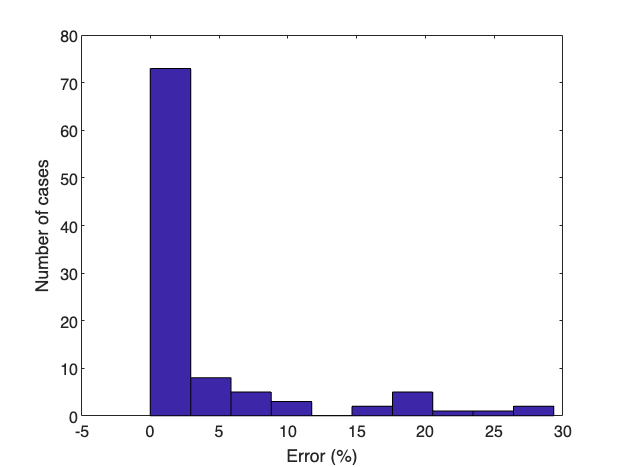

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% 5. Perform some analysis. Do the location of zeros matter? Plot
% histograms, etc.
figure;
hist([scenario.error]*100)
ylabel('Number of cases');
xlabel('Error (%)');
matlab2tikz('hist.tex')

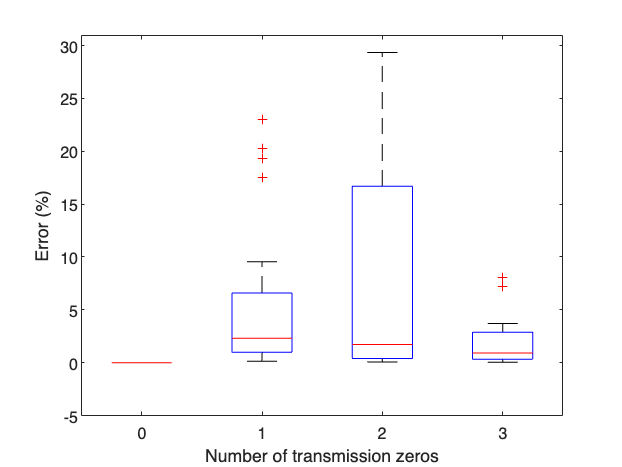

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.4 or newer to compile the TikZ output.



% Collect some more statistics
for i = 1:Ns
    A = scenario(i).A;
    C = scenario(i).C;
    F = scenario(i).F;
    G = scenario(i).G;
    Sf = ss(A,F,C,G,dt);
    z = tzero(Sf,1e-8);
    scenario(i).nmp = any(abs(z)>1);
    dtuc = nan;
    if scenario(i).nz >= 1
        dtuc = min(abs(abs(z)-1));
    end
    scenario(i).distance_to_unit_circle = dtuc;
end

figure;
boxplot([scenario.error]*100, [scenario.nz])
xlabel('Number of transmission zeros');
ylabel('Error (%)');
matlab2tikz('box_nz.tex')

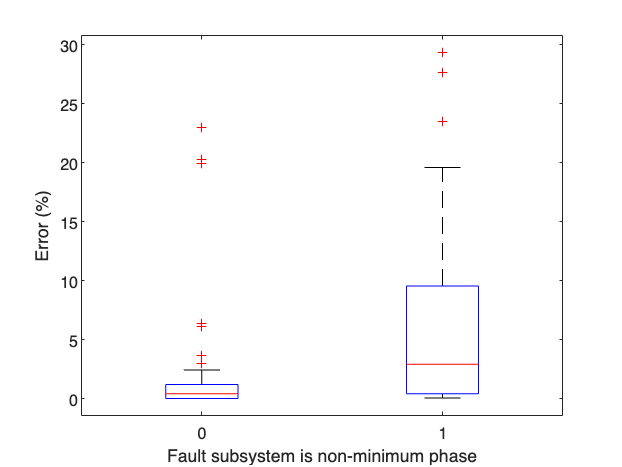

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.




figure;
boxplot([scenario.error]*100, [scenario.nmp])
xlabel('Fault subsystem is non-minimum phase');
ylabel('Error (%)');
matlab2tikz('box_nmp.tex')

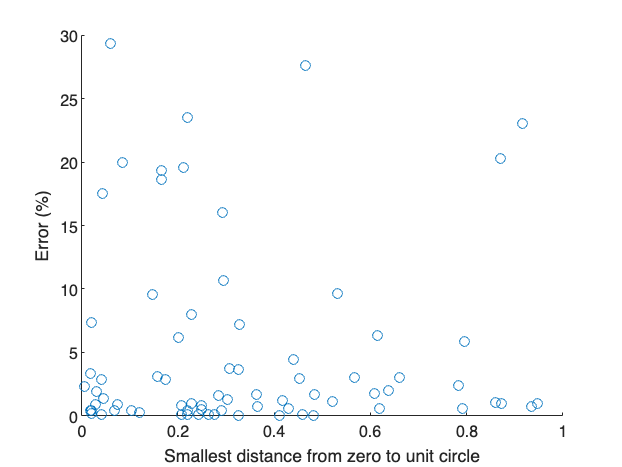

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.



figure;
scatter([scenario.distance_to_unit_circle], [scenario.error]*100)
xlabel('Smallest distance from zero to unit circle');
ylabel('Error (%)');
matlab2tikz('scatter_dist_unit_circle.tex')